# Solve a Mixed-Integer Engineering Design Problem Using the Genetic Algorithm, Problem-Based

This example shows how to solve a mixed-integer engineering design problem using the genetic algorithm (`ga`) solver in Global Optimization Toolbox. The example uses the problem-based approach. For a version using the solver-based approach, see [docid:gads.btjfuy5](docid:gads.btjfuy5). 

The problem illustrated in this example involves the design of a stepped cantilever beam. In particular, the beam must be able to carry a prescribed end load. The optimization problem is to minimize the beam volume subject to various engineering design constraints.

This problem is described in Thanedar and Vanderplaats [1].

## Stepped Cantilever Beam Design Problem

A stepped cantilever beam is supported at one end, and a load is applied at the free end, as shown in the following figure. The beam must be able to support the given load $P$ at a fixed distance $L$ from the support. Designers of the beam can vary the width ($b_i$) and height ($h_i$) of each step, or section. Each section of the cantilever has the same length, $l=L_1$. 

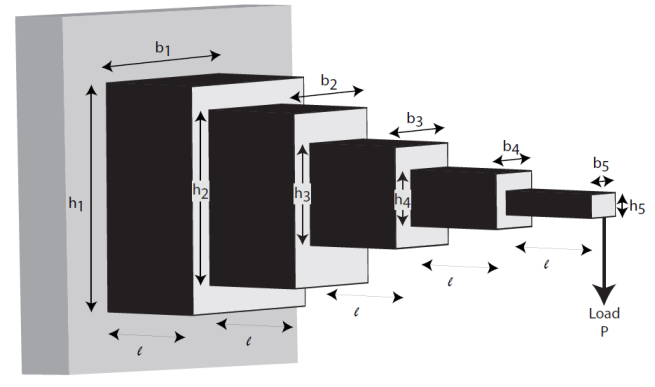

### Volume of the Beam

The volume of the beam $V$ is the sum of the volume of the individual sections.

$V = l(b_1h_1 + b_2h_2 + b_3h_3 + b_4h_4 + b_5h_5)$.

### Constraints on the Design: Bending Stress

Consider a single cantilever beam, with the center of coordinates at the center of its cross section at the free end of the beam. The bending stress at a point $(x, y, z)$ in the beam is given by the equation

$\sigma_b = M(x)y/I$,

where $M(x)$ is the bending moment at $x$, $x$ is the distance from the end load, and $I$ is the area moment of inertia of the beam. 

In the stepped cantilever beam shown in the figure, the maximum moment of each section of the beam is $PD_i$, where $D_i$ is the maximum distance from the end load $P$ for each section of the beam. Therefore, the maximum stress for the *i*th section of the beam $\sigma_i$ is given by

$\sigma_i = PD_i(h_i/2)/I_i$,

where the maximum stress occurs at the edge of the beam, $y = h_i/2$. The area moment of inertia of the *i*th section of the beam is given by

$I_i = b_ih_i^3/12$.

Substituting this expression into the equation for $\sigma_i$ gives

$\sigma_i = 6PD_i/b_ih_i^2$.

The bending stress in each part of the cantilever must not exceed the maximum allowable stress $\sigma_{max}$. Therefore, the five bending stress constraints (one for each step of the cantilever) are:


$$\frac{6Pl}{b_5h_5^2} \leq \sigma_{max}$$



$$\frac{6P(2l)}{b_4h_4^2} \leq \sigma_{max}$$



$$\frac{6P(3l)}{b_3h_3^2} \leq \sigma_{max}$$



$$\frac{6P(4l)}{b_2h_2^2} \leq \sigma_{max}$$



$$\frac{6P(5l)}{b_1h_1^2} \leq \sigma_{max}$$


### Constraints on the Design: End Deflection

You can calculate the end deflection of the cantilever using Castigliano's second theorem, which states that 

$\delta = \frac{\partial U}{\partial P}$,

where $\delta$ is the deflection of the beam, and $U$ is the energy stored in the beam due to the applied force $P$.

The energy stored in a cantilever beam is given by

$U = \int_0^L \! M^2/2EI \, \mathrm{d} x$,

where $M$ is the moment of the applied force at $x$.

Given that $M = Px$ for a cantilever beam, you can write the preceding equation as 

$U = 
P^2/2E \int_0^l \! [(x+4l)^2/I_1 \, 
            + (x+3l)^2/I_2 \, 
            + (x+2l)^2/I_3 \, 
            + (x+l)^2/I_4 \, 
            + x^2/I_5 ]\, \mathrm{d} x$,

where $I_n$ is the area moment of inertia of the *n*th part of the cantilever. Evaluating the integral gives this expression for $U$

$U = (P^2/2)(l^3/3E)(61/I_1 + 37/I_2 + 19/I_3 + 7/I_4 + 1/I_5)$.

Applying Castigliano's theorem, the end deflection of the beam is given by

$\delta = Pl^3/3E(61/I_1 + 37/I_2 + 19/I_3 + 7/I_4 + 1/I_5)$.

The end deflection of the cantilever $\delta$ must be less than the maximum allowable deflection $\delta_{max}$, which gives the constraint

$Pl^3/3E(61/I_1 + 37/I_2 + 19/I_3 + 7/I_4 + 1/I_5) \leq
\delta_{max}$.

### Constraints on the Design: Aspect Ratio

For each step of the cantilever, the aspect ratio must not exceed a maximum allowable aspect ratio $a_{max}$. That is, 

$h_i/b_i \leq a_{max}$ for $i = 1, ..., 5$.

### Constraints on the Design: Bounds and Integer Constraints

The first step of the beam can be machined to the nearest centimeter only. That is, $b_1$ and $h_1$ must be integers. The remaining variables are continuous. The bounds on the variables are:


$$1 \leq b_1 \leq 5$$



$$30 \leq h_1 \leq 65$$



$$2.4 \leq b_2, b_3 \leq 3.1$$



$$45 \leq h_2, h_3 \leq 60$$



$$1 \leq b_4, b_5 \leq 5$$



$$30 \leq h_4, h_5 \leq 65$$


### Design Parameters for This Problem

For the problem in this example, the end load that the beam must support is $P = 50000 N$.

The beam lengths and maximum end deflection are:

- Total beam length, $L = 500 cm$

- Length of an individual section of the beam, $l = L_1 = 100 cm$

- Maximum beam end deflection, $\delta_{max} = 2.7 cm$

The maximum allowed stress in each step of the beam is $\sigma_{max} = 14000 N/cm^2$.

Young's modulus of each step of the beam is $E = 2\times10^{7} N/cm^2$.

## Problem-Based Setup

Create optimization variables for this problem. The width and height variables for the first section of the beam are of type integer, so you must create them separately from the other four variables, which are continuous.

b1 = optimvar("b1","Type","integer","LowerBound",1,"UpperBound",5);
h1 = optimvar("h1","Type","integer","LowerBound",30,"UpperBound",65);
bc = optimvar("bc",4,"LowerBound",[2.4 2.4 1 1],"UpperBound",[3.1 3.1 5 5]);
hc = optimvar("hc",4,"LowerBound",[45 45 30 30],"UpperBound",[60 60 65 65]);

For convenience, put the height and width variables into single variables. You can then express the objective and constraints easily in terms of these variables.

h = [h1;hc];
b = [b1;bc];

Create an optimization problem with the volume of the beam as the objective function, where each step (or section) of the beam is $L_1 =100$ cm long: volume = $L_1\sum h_i w_i $.

L_1 = 100; % Length of each step of the cantilever
prob = optimproblem("Objective",L_1*dot(h,b));

Create the constraints on the stress.

P = 50000; % End load
E = 2e7; % Young's modulus in N/cm^2
deltaMax = 2.7; % Maximum end deflection
sigmaMax = 14000; % Maximum stress in each section of the beam
aMax = 20; % Maximum aspect ratio in each section of the beam

stress = 6*P*L_1./(b.*(h.^2));
stepnum = (5:-1:1)';
stress = stress.*stepnum;
prob.Constraints.stress = stress <= sigmaMax;

Create the constraint on the deflection.

deflectionMultiplier = (P*L_1^3/E)*[244 148 76 28 4];
bh3 = 1./(b.*(h.^3));
prob.Constraints.deflection = deflectionMultiplier*bh3 <= deltaMax;

Create the constraints on the aspect ratio.

prob.Constraints.aspect = h <= aMax*b;

Review the problem setup.

show(prob)

## Solve the Problem

Set options to use a moderate population size of 150, a moderate maximum number of generations of 400, a slightly larger than default elite count of 10, a small function tolerance of 1e-8, and a plot function showing the function value during the iterations.

opts = optimoptions(@ga, ...
                    'PopulationSize', 150, ...
                    'MaxGenerations', 400, ...
                    'EliteCount', 10, ...
                    'FunctionTolerance', 1e-8, ...
                    'PlotFcn', @gaplotbestf);

Solve the problem, specifying the `ga` solver and the options.

rng default % For reproducibility
[sol,fval,exitflag] = solve(prob,"Solver","ga","Options",opts)

View the solution variables and their bounds.

widths = [sol.b1;sol.bc];
heights = [sol.h1;sol.hc];
widthbounds = [b1.LowerBound b1.UpperBound;
    bc.LowerBound bc.UpperBound];
heightbounds = [h1.LowerBound h1.UpperBound;
    hc.LowerBound hc.UpperBound];
T = table(widths,heights,widthbounds,heightbounds,...
    'VariableNames',["Width" "Height" "Width Bounds" "Height Bounds"])

The solution is not at any of the bounds. The first solution variables are integer valued, as specified.

## Add Discrete Noninteger Variable Constraints

Suppose the engineers learn that the second and third steps of the cantilever can have widths and heights selected from a standard set only. With the addition of this constraint, the problem is identical to the one solved in [1].

First, delineate the extra constraints to add to the optimization:

- The width of the second and third steps of the beam must be selected from the set [2.4, 2.6, 2.8, 3.1] cm.

- The height of the second and third steps of the beam must be selected from the set [45, 50, 55, 60] cm.

To solve this problem, you need to specify the variables $wc(1)$, $wc(2)$, $hc(1)$, and $hc(2)$ as discrete variables. Ideally, you would use $S(x_j)$ as the discrete value, where $S$ represents the allowable set of values and $x_j$ represents a problem variable. However, you cannot use an optimization variable as an index. You can get around this problem by calling `fcn2optimexpr`.

widthlist = [2.4,2.6,2.8,3.1];
heightlist = [45 50 55 60];
b23 = optimvar("w23",2,"Type","integer",...
    "LowerBound",1,"UpperBound",length(widthlist));
h23 = optimvar("h23",2,"Type","integer",...
    "LowerBound",1,"UpperBound",length(heightlist));
b45 = optimvar("b45",2,"LowerBound",1,"UpperBound",5);
h45 = optimvar("h45",2,"LowerBound",30,"UpperBound",65);
% Preferred syntax is we = [widthlist(b23(1));widthlist(b23(2))];
% However, this syntax is illegal.
% Instead call fcn2optimexpr.
we = fcn2optimexpr(@(x)[widthlist(x(1));widthlist(x(2))],b23);
he = fcn2optimexpr(@(x)[heightlist(x(1));heightlist(x(2))],h23);

As you did earlier, create the expressions `b` and `h` to represent the variables.

b = [b1;we;b45];
h = [h1;he;h45];

The remainder of the problem formulation is the same as earlier.

prob2 = optimproblem("Objective",L_1*dot(h,b));

Create the constraints on the stress.

stress = 6*P*L_1./(b.*(h.^2));
stepnum = (5:-1:1)';
stress = stress.*stepnum;
prob2.Constraints.stress = stress <= sigmaMax;

Create the constraint on the deflection.

deflectionMultiplier = (P*L_1^3/E)*[244 148 76 28 4];
bh3 = 1./(b.*(h.^3));
prob2.Constraints.deflection = deflectionMultiplier*bh3 <= deltaMax;

Create the constraints on the aspect ratio.

prob2.Constraints.aspect = h <= aMax*b;

Review the problem setup.

show(prob2)

## Solve the Problem with Discrete Variable Constraints

Solve the problem, specifying the `ga` solver and the options.

rng default % For reproducibility
[sol2,fval2,exitflag2] = solve(prob2,"Solver","ga","Options",opts)

The objective value increases, because adding constraints can only increase the objective.

View the solution and compare it to its bounds.

widths = [sol2.b1;widthlist(sol2.w23(1));widthlist(sol2.w23(2));sol2.b45];
heights = [sol2.h1;heightlist(sol2.h23(1));heightlist(sol2.h23(2));sol2.h45];
widthbounds = [b1.LowerBound b1.UpperBound;
    widthlist(1) widthlist(end);
     widthlist(1) widthlist(end);
    b45.LowerBound b45.UpperBound];
heightbounds = [h1.LowerBound h1.UpperBound;
     heightlist(1) heightlist(end);
     heightlist(1) heightlist(end);
    h45.LowerBound h45.UpperBound];
T = table(widths,heights,widthbounds,heightbounds,...
    'VariableNames',["Width" "Height" "Width Bounds" "Height Bounds"])

The only solution variable that is at a bound is the width of the second section, which is 3.1, its maximum.

## References

[1] Thanedar, P. B., and G. N. Vanderplaats. "Survey of Discrete Variable Optimization for Structural Design."* Journal of Structural Engineering* 121 (3), 1995, pp. 301–306.

*Copyright 2021 The MathWorks, Inc.*